# Simple Example

This is a simple example of using regularizeNd.

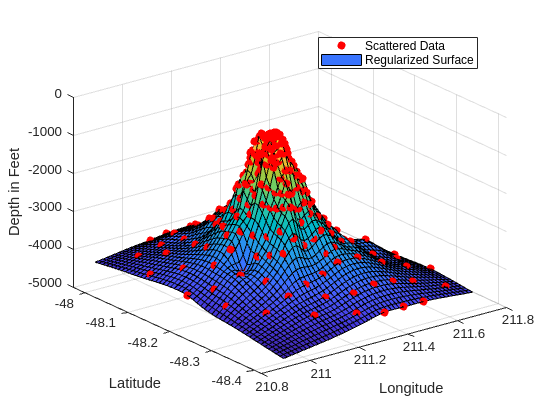

clc; clear; close all;
load('seamount')

xLimits = [min(x), max(x)];
yLimits = [min(y), max(y)];

xGrid = {linspace(xLimits(1) - eps(xLimits(1)), xLimits(2) + eps(xLimits(2)), 50), ...
         linspace(yLimits(1) - eps(yLimits(1)), yLimits(2) + eps(yLimits(2)), 51)};

smoothness = 0.0001;
     
zGrid = regularizeNd([x,y], z, xGrid, smoothness, 'cubic');
% equivalents ways to call regularizeNd
% zGrid = regularizeNd([x,y], z, xGrid, smoothness, 'cubic');
% zGrid = regularizeNd([x,y], z, xGrid, smoothness, 'cubic', 'normal');


scatter3(x,y,z,[], 'r', 'filled')
hold all;
surf(xGrid{:}, zGrid')
xlabel('Longitude')
ylabel('Latitude')
zlabel('Depth in Feet')
grid on
legend({'Scattered Data', 'Regularized Surface'}, 'location', 'best');